clear Hil;clc;close all
 

## General Settings

#### Model Selection

Sim.HilModelName         = 'SpeedGoat_GridModel';
Sim.ADC_UabcSensor      = "Three Currents";              % 0 == Meas AB only, 1 == Meas ABC
Sim.HilModel              = "System 2";
Sim.PwmModel            = "Average";

#### **Runtime Setting**

Sim.RunTime         = 1;
Sim.ContSampleTime  = ((10)*1e-6);
Hil.MeasLogTime          = ((100));
Hil.MeasFastSmplTime    = ((10)*1e-6);
Hil.MeasSlowSmplTime    = ((10)*1e-6);
Hil.MeasFastLogLim         =round(Hil.MeasLogTime/Hil.MeasFastSmplTime );
Hil.MeasSlowLogLim         =round( Hil.MeasLogTime/Hil.MeasSlowSmplTime) ;

## Plant Model

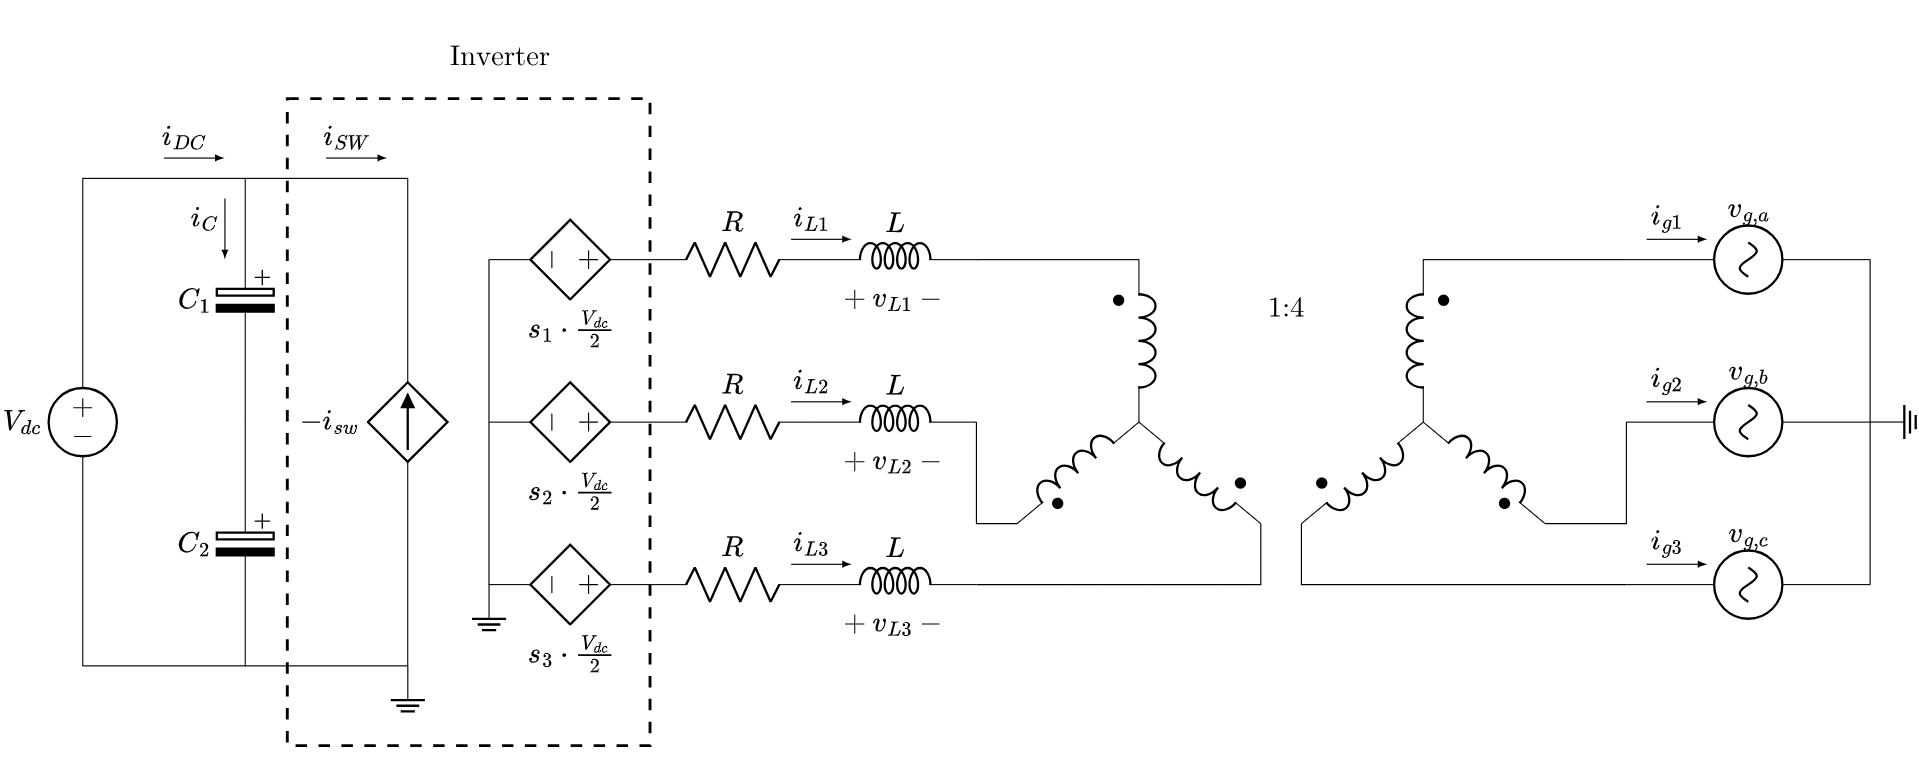

### HVDC

Hil.HVDC_V              = (650); 
Hil.HVDC_Vesr           = 10e-3;
Hil.HVDC_Vesl           = 1e-6;
Hil.HVDC_C              = (260*1e-6);
Hil.HVDC_Cesr           = (50e-3); % 0.05 Ω to 0.3 Ω
Hil.HVDC_Cesl           = (10e-9); % 10 nH to 50 nH
Hil.HVDC_Rpasiv         = (385e3); %R≈385kΩ

### Grid Settings

% Grid Voltage
Hil.Grid_VphRms         = (220);
Hil.Grid_Frq            = (50);
Hil.Harm_Freq           = [3 5 7];
Hil.Harm_Amp            =[0 5/100 2.5/100];

% Connection Inductance
Hil.Inductor_L          = (2000*1e-6);
Hil.Inductor_R          = (1000*1e-3);
Hil.Inductor_C          = (20*1e-6);
Hil.Inductor_Lg          = (3000*1e-6);
Hil.Inductor_Rg          = (200*1e-3);
% Connection Transformer
Hil.Transformer_N          = (4);
Hil.Transformer_R1          = (0.0992);
Hil.Transformer_R2          = (0.3);
Hil.Transformer_L1          = (0.6613e-3);
Hil.Transformer_L2          = (2e-3);
Hil.Transformer_Rc          = (1e3);
Hil.Transformer_Lm          = (0.4959);

### PWM Adjustments

Hil.PWM_Freq            = (10*1e3);
Hil.PWM_Deadtime        = (0*1e-6);

% Power Modules
Hil.Sic_Ron = 47e-3;
Hil.Sic_Vdiode = 1.7;
Hil.Sic_Rdiode = 55e-3;

% Sensors
    
% Gain
Hil.ADC_CH0_PHY_Gain    = (2000/3); % Va
Hil.ADC_CH1_PHY_Gain    = (2000/3); % Vb
switch Sim.ADC_UabcSensor
    case "Three Currents"
        Hil.ADC_CH2_PHY_Gain    = (200/3); % Ia
    case "Three Volts"
        Hil.ADC_CH2_PHY_Gain    = (2000/3); % Vc
end
Hil.ADC_CH3_PHY_Gain    = (200/3);  % Ib
Hil.ADC_CH4_PHY_Gain    = (200/3);  % Ic
Hil.ADC_CH5_PHY_Gain    = (2000/3); % Vdc
    
% Offset
Hil.ADC_CH0_PHY_OFFSET  = (1.5+0/Hil.ADC_CH0_PHY_Gain );
Hil.ADC_CH1_PHY_OFFSET  = (1.5+0/Hil.ADC_CH1_PHY_Gain );
Hil.ADC_CH2_PHY_OFFSET  = (1.5+0/Hil.ADC_CH2_PHY_Gain ); 
Hil.ADC_CH3_PHY_OFFSET  = (1.5+0/Hil.ADC_CH3_PHY_Gain ); 
Hil.ADC_CH4_PHY_OFFSET  = (1.5+0/Hil.ADC_CH4_PHY_Gain );
Hil.ADC_CH5_PHY_OFFSET  = (1.5+10.0122/Hil.ADC_CH5_PHY_Gain );

% Noise 
Hil.ADC_VgnoiseStd       = [1.8625 1.8326 2.0763];
Hil.ADC_InoiseStd       = [0.1803 0.2147 0.3315];
Hil.ADC_VdcnoiseStd       = 1.4157;
